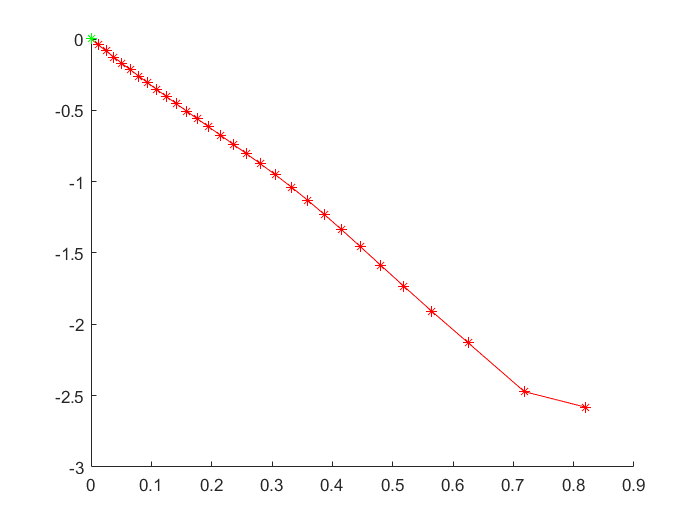

x_global =          0
    0.0123
    0.0250
    0.0379
    0.0513
    0.0650
    0.0792
    0.0939
    0.1091
    0.1249


%x_global = linspace(0,pi,10);
%y_global = sin(x_global*2);
%x_global = [0,x_global+1];
%y_global = [0,y_global];
%x_global = [0,1,1,0,0,1,1,0];
%y_global = [0,0,1,1,2,2,3,4];
load points_to_go_to.mat
%clf; hold on;
%plot(x_global,y_global,"r*-")
%plot(0,0,"g*")


wheelBase = 0.235;
angular_speed = 0.5; %rad per sec
linear_speed = 0.1; %meters per sec

%how much does x and y change
change_x = [diff(x_global)];
change_y = [diff(y_global)];

disp('Program has begun, initializing rossubscribers and LIDAR')
pub = rospublisher('/raw_vel'); %sets motor data
scan = rossubscriber('/scan'); %gets LIDAR data
encoder_listener = rossubscriber('/encoders'); %gets encoder data
sub_states = rossubscriber('/gazebo/model_states', 'gazebo_msgs/ModelStates');
msg = rosmessage(pub); %sends motor power


n = 3

%stuff for LIDAR
theta = deg2rad([0:359]'); %define once, this is the position for each LIDAR sensor
% define distance from neato center to lidar array center
lidar_offset.y = 0; 
lidar_offset.x = -0.0840;
% define number of LIDAR sensors
lidar_sensor_count = 360;
wheel_spacing = 0.235; %meters
wheel_diameter = 0.070;
zero_expansion_array = zeros(lidar_sensor_count,1);
controlFlag = 1;


distance = 1

real_position_storage = [zeros(1,8)]; %posX posY posZ rotX rotY rotZ controlFlag rostoc
[real_position_storage(1,1),real_position_storage(1,2),real_position_storage(1,3),real_position_storage(1,4),real_position_storage(1,5),real_position_storage(1,6)] = getNeatoPosition(receive(sub_states));
encoder_position_storage = [zeros(1,6)]; %setL setR encoderL encoderR controlFlag rostoc

ans = 90

%the zeros in encoder_position_storage are important
lidar_storage = [zeros(1,6)]; %lidarR lidarTheta lidarXGlobal lidarYGlobal controlFlag rostoc


% get robot into positon -------------------------
% dont get the robot moving yet
msg.Data = [0, 0];
send(pub, msg);
disp("Placing robot in positon")
placeNeato(0,0,1,0); %initial position
pause(2); %wait for robot to settle
clear store_position
disp("driving");

%posX = 0;
%posY = 0;
%rotX = deg2rad(0);
%[posX, posY, posZ, rotX, rotY, rotZ] = getNeatoPosition(receive(sub_states));
%store_position = [posX,posY,posZ,rotX];

for n = [2:size(x_global,1)]
    controlFlag = n;
    Velocities = [0,0];
    %get position
    n
    [posX, posY, posZ, rotX, rotY, rotZ] = getNeatoPosition(receive(sub_states));
    %store_position(n,:) = [posX,posY,posZ,rotX];
    
    %do math
    pts_X = [posX,x_global(n)];
    pts_Y = [posY,y_global(n)];
    dx = diff(pts_X); dy = diff(pts_Y);
    distance = sqrt(dx.^2+dy.^2) %how far do we have to go
    new_heading = atan2(dy,dx);
    dHeading = diff([rotX,new_heading]); %how far do we have to turn?
    
    %calculate anglar motor commands
    angular_time = double(dHeading)./angular_speed;
    turn_direction = sign(dHeading);
    angular_x_power = [-turn_direction.*angular_speed.*(wheelBase/2)]; %update motor powers
    angular_y_power = [turn_direction.*angular_speed.*(wheelBase/2)];

motor_powers =          0         0         0
    0.5000    0.5000         0
   -0.0587    0.0587    2.1466
    0.5000    0.5000    2.0000
    0.0587   -0.0587    0.5962
    0.5000    0.5000    1.4629
    0.0587   -0.0587    2.2064
    0.5000    0.5000    0.9774
    0.0587   -0.0587    1.3103
    0.5000    0.5000    0.7374


    
    %execute angular motor commands
    start_time = getTime();
    msg.Data = [angular_x_power, angular_y_power];
    send(pub,msg);
    while now <= abs(angular_time)+start_time %drive forward set time
       now = getTime();
       send(pub,msg);
    end
    stop_moving(pub,msg); %stop moving
    
    %calculate linear motor commands
    linear_time = distance./linear_speed;
    
    %execute linear motor commands
    start_time = getTime();
    msg.Data = [linear_speed, linear_speed];
    send(pub,msg);
    while now <= abs(linear_time)+start_time %drive forward set time
       now = getTime();
       send(pub,msg);
    end
    stop_moving(pub,msg); %stop moving
    
    %get lidar data here
%    [posX, posY, rotX, real_position_storage] = get_and_store_position(real_position_storage,sub_states,controlFlag,now); %true position
    
    
%    if or((controlFlag==1),(mod(controlFlag,10)==0)) %only aquire LIDAR data if this is loop 1 or any multiple of 10
%        [lidar_storage] = get_and_store_LIDAR(lidar_storage,scan,theta,posX,posY,rotX,lidar_offset,zero_expansion_array,controlFlag,now,sub_states); %lidar data    
%    end
end
[posX, posY, posZ, rotX, rotY, rotZ] = getNeatoPosition(receive(sub_states));
store_position(n,:) = [posX,posY,posZ,rotX];


disp("end");
beep
msg.Data = [0, 0];
send(pub, msg);
%clf; hold on
%plot(x_global,y_global,"bo--","DisplayName","Planned")
%plot(store_position(:,1),store_position(:,2),"r.-","DisplayName","Actual");
%legend(); axis equal;

lidar_storage = lidar_storage(2:end,:); %trim the leading zeros that we don't need
save DriveCodeV4_Storage_1.mat lidar_storage real_position_storage x_global y_global
disp("Done Moving and Saving Data");
beep

function [posX, posY, posZ, rotX, rotY, rotZ] = getNeatoPosition(msg) %get neato position in XYZ
    for i = 1 : length(msg.Name)
        if strcmp(msg.Name{i}, 'neato_standalone')
            %position (x y z global)
            posX = msg.Pose(i).Position.X;
            posY = msg.Pose(i).Position.Y;
            posZ = msg.Pose(i).Position.Z;
            %orientation (quaternation format)
            quatX = msg.Pose(i).Orientation.X;
            quatY = msg.Pose(i).Orientation.Y;
            quatZ = msg.Pose(i).Orientation.Z;
            quatW = msg.Pose(i).Orientation.W;
            rotation = quat2eul([quatW,quatX,quatY,quatZ]); %convert quaternation coordinates to euler, allowing for x y z rotation
            rotX = rotation(1);
            rotY = rotation(2);
            rotZ = rotation(3);
            return
        end
    end
end

function time_now = getTime()
    now = rostime("now");
    time_now = now.Sec+(now.Nsec*10^(-9));
end

function stop_moving(pub,msg)
    msg.Data = [0,0];
    send(pub,msg);
end

function [posX, posY, rotX, real_position_storage] = get_and_store_position(real_position_storage,sub_states,controlFlag,now)
    %storage_format: posX posY posZ rotX rotY rotZ controlFlag rostoc
    [posX, posY, posZ, rotX, rotY, rotZ] = getNeatoPosition(receive(sub_states)); %aquire data
    real_position_storage = [real_position_storage;posX, posY, posZ, rotX, rotY, rotZ, controlFlag,now]; %store data
end

function [encoder_position_storage] = get_and_store_encoder(encoder_position_storage,encoder_listener,Velocities,controlFlag,now)
    %setL setR encoderL encoderR controlFlag rostoc
    encoders = receive(encoder_listener).Data;
    encoder_position_storage = [encoder_position_storage;Velocities(1,1),Velocities(1,2),encoders(1,1),encoders(2,1),controlFlag,now];
end

function [lidar_storage] = get_and_store_LIDAR(lidar_storage,scan,theta,posX,posY,rotX,lidar_offset,zero_expansion_array,controlFlag,now,sub_states)
    %storage_format: lidarR lidarTheta lidarXGlobal lidarYGlobal controlFlag rostoc
    %scan
    scan_message = receive(scan);
    r = scan_message.Ranges(1:end-1);
    
    [x_temp,y_temp] = pol2cart(theta,r); %convert from polar to cartesian
    
    % change frame
    [x_temp,y_temp] = local2global(x_temp,y_temp,lidar_offset.x,lidar_offset.y,0); %convert to neato frame
    [posX, posY, ~, rotX, ~, ~] = getNeatoPosition(receive(sub_states)); %aquire more accurate data, if we use the data collected earlier the scan location is significantly wrong
    [x_temp,y_temp] = local2global(x_temp,y_temp,posX,posY,rotX); %convert to global frame
    
    % prep variables for storage
    controlFlag = controlFlag+zero_expansion_array; % expand so that it can be stored
    now = now+zero_expansion_array; % expand so that it can be stored
    
    % store variables
    lidar_storage = [lidar_storage;r,theta,x_temp,y_temp,controlFlag,now];
    
end

**Conversion Functions**

function [x,y] = local2global(x_in,y_in,x_offset,y_offset,offset_angle,degree_mode)
    % local2global
    % Version 1.0, Written by Chris Sanchez on 26-April-2021
    % function for converting coordiantes in a local space into a global space
    % Inputs:
    %   x_in: series of x points to convert, can be one point or a n by 1 matrix
    %   y_in: series of y points to convert, can by one point or a n by 1 matrix
    %   x_offset: x offset of the local coordinate space
    %   y_offset: y offset of the local coordinate space
    %   offset_angle: angle offset of the local coordinate space (rotates clockwise)
    %   degree mode: what units was offset_angle? (must be "degrees" or "radians"), if not provided, program will assume input was in radians
    % Returns:
    %    x: converted x points, either as one point or an n by 1 matrix
    %    y: converted y points, either as one point or an n by 1 matrix
    
    %process input for degree_mode
    if nargin<6
        degree_mode = "radians";
    end
    if degree_mode == "degrees"
        offset_angle = deg2rad(offset_angle);
    end
    
    %check for incorrect x and y inputs
    warnings.x = 0; warnings.y = 0; %setup variables for error logging
    if (size(x_in,1) == 1) && (size(x_in,2) > 1)
        x_in = x_in';
        warnings.x = 1;
    end
    if (size(y_in,1) == 1) && (size(y_in,2) > 1)
        y_in = y_in';
        warnings.y = 1;
    end
    %display warnings
    if (warnings.x == 1) && (warnings.y == 1)
        warning("Incorrect Input Dimensions: x_in and y_in were 1 by n matrixes instead of n by 1. They have been transposed.")
    elseif (warnings.x == 1)
        warning("Incorrect Input Dimensions: x_in was a 1 by n matrix instead of n by 1. It has been transposed.")
    elseif (warnings.y == 1)
        warning("Incorrect Input Dimensions: y_in was a 1 by n matrix instead of n by 1. It has been transposed.")
    end
    %check for mismatched sizes
    if size(x_in,1)~=size(y_in,1)
        error("Dimension Mismatch: x_in and y_in are different sizes. Please check inputs and try again");
    end
    
    x = zeros(size(x_in,1),1); %setup output matrix
    y = x;
    
    Translation_Matrix = [1, 0, x_offset; 0, 1, y_offset; 0, 0, 1]; %setup translation matrix
    Rotation_Matrix = [cos(offset_angle),-sin(offset_angle),0; sin(offset_angle),cos(offset_angle), 0; 0,0,1]; %setup rotation matrix
    
    %do math
    for point = [1:size(x,1)]
        XY_Matrix = [x_in(point,1);y_in(point,1);1]; %put the X and Y points into a matrix
        R = Translation_Matrix*Rotation_Matrix*XY_Matrix; %do math
        x(point,1) = R(1); %store variables
        y(point,1) = R(2);
    end
end
